# Basic MATLAB Image Processing

Read an image

I = imread("Imagepro/mr_brain.jpg");
whos("I")

  Name        Size                Bytes  Class    Attributes

  I         256x256x3            196608  uint8              



Display the image

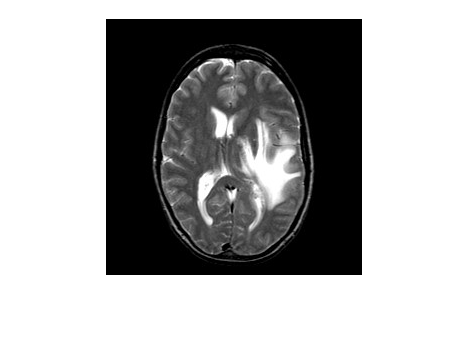

imshow(I)

Display a matrix as an image using `imagesc` and `colormap`

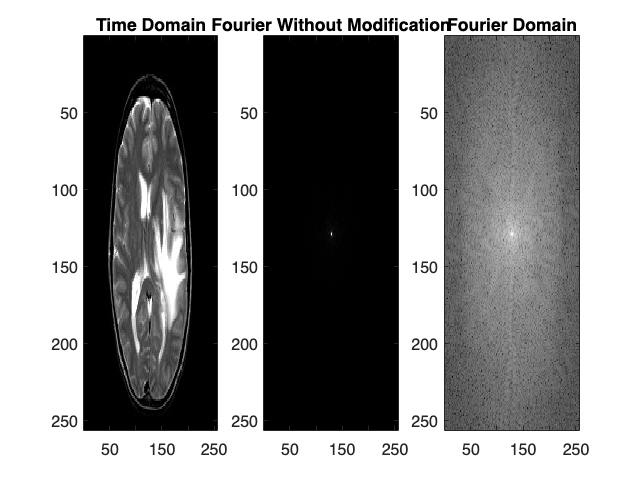

% Transform RBG to grayscale
pic=rgb2gray(I);
figure
subplot(1,3,1)
imagesc(pic);
title('Time Domain')
colormap(gray)
subplot(1,3,2)
% The Fourier transformed image
imagesc(fftshift(abs(fft2(pic))));
title('Fourier Without Modification');
subplot(1,3,3)
% The Fourier transformed image after the logarithm transform
qb = fftshift(log(abs(fft2(pic))));
imagesc(qb);
title('Fourier Domain')
colormap(gray)